clear all
clc
addpath('dynamics/')

% parameter
% link length
l1 = 0.33; 
l2 = 0.33;
l3 = 0.33;

% link masses
% m1 = 10; %0.1
% m2 = 1;
% m3 = 2;
m1 = 0.1;
m2 = 0.1;
m3 = 0.1;

% link inertias
% I1 = [1 2 5 0 1 1]; %[Ixx Iyy Izz Iyz Ixz Ixy]. %[ 1 1 1 0 0 0]
% I2 = [3 1 5 0 0 1];
% I3 = [1 2 1 1 0 0];

I1 = [ 1 1 1 0 0 0];
I2 = [ 1 1 1 0 0 0];
I3 = [ 1 1 1 0 0 0];
% COM
COM1 = [l1/2 0 0]; % [x y z] in body frame
COM2 = [l2/2 0 0]; % [x y z] in body frame
COM3 = [l3/2 0 0]; % [x y z] in body frame

% dh params

dt = 0.005;
num_snaps = 1000;
num_traj = 125;
t_span = 0:dt:dt*num_snaps;
num_states = 3;


% 2D
for i = 1:num_traj
    i
    % Initialize the values
    X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1); %joint angles
    X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1); %joint velocity
    X_end(i,1,:) = forward_map_3R(X(i,1,1:num_states));
    for j = 1:num_snaps
        tau(i,j,:) = 1*(2*rand(1,num_states) - 1); %input torques
% 
        [X(i,j+1,1:num_states),X(i,j+1,num_states+1:2*num_states)] = dynamics_3R(reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]), reshape(tau(i,j,:),[num_states,1]));

        X_end(i,j+1,:) = forward_map_3R(reshape(X(i,j+1,1:num_states),[num_states,1]));

    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

% % controller
% 
% Kp = 16*eye(num_states);
% Kv = 8*eye(num_states);
% num_wp = 10;
% flag = 'random'; %'controlled'
% 
% for i = 1:num_traj
%     i% controller
% 
% Kp = 16*eye(num_states);
% Kv = 8*eye(num_states);
% num_wp = 10;
% flag = 'random'; %'controlled'
% 
% for i = 1:num_traj
%     i
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [1;10;1;1;0.1;0.1;0.1];
%     l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
% 
% 
%     % generate path
%     t_end = dt*num_snaps; 
%     for s = 1:num_wp
%         if s == 1
%             q_wp(:,1) = (pi/2)*(2*rand(num_states,1) - 1);
%             t_wp(:,1) = 0;
%             q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
%         else
%             t_wp(s) = s*t_end/num_wp;
% %             q_wp(:,s) = randomConfiguration(kuka)';
%             q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
%             q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
%         end
% 
%     end
% 
%     [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));
% 
% 
%     % Initialize the values
%     X(i,1,1:num_states) = q_traj(:,1);%.*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = qd_traj(:,1);%.*ul_joints; %joint velocity
%     % X(i,1,2*num_states+1:3*num_states) = qddot_traj(:,1);
%     X_end(i,1,:) = forward_map_3R(X(i,1,1:num_states));
%     for j = 1:num_snaps
% 
%         tau_dash(:,j) = qddot_traj(:,j) + Kv*(qd_traj(:,j) - reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) + Kp*(q_traj(:,j) - reshape(X(i,j,1:num_states),[num_states,1]));
%         [M,C,G] = dynamics_matrix_3R(reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]));
%         tau(i,j,:) = M*tau_dash(:,j) + C*reshape(X(i,j,num_states+1:2*num_states),[num_states,1]) + G;
% 
%        [X(i,j+1,1:num_states),X(i,j+1,num_states+1:2*num_states)] = dynamics_3R(reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]), reshape(tau(i,j,:),[num_states,1]));
% 
%        X_end(i,j+1,:) = forward_map_3R(reshape(X(i,j+1,1:num_states),[num_states,1]));
% 
%     end
% end
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [1;10;1;1;0.1;0.1;0.1];
%     l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
% 
% 
%     % generate path
%     t_end = dt*num_snaps; 
%     for s = 1:num_wp
%         if s == 1
%             q_wp(:,1) = (pi/2)*(2*rand(num_states,1) - 1);
%             t_wp(:,1) = 0;
%             q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
%         else
%             t_wp(s) = s*t_end/num_wp;
% %             q_wp(:,s) = randomConfiguration(kuka)';
%             q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
%             q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
%         end
% 
%     end
% 
%     [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));
% 
% 
%     % Initialize the values
%     X(i,1,1:num_states) = q_traj(:,1);%.*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = qd_traj(:,1);%.*ul_joints; %joint velocity
%     % X(i,1,2*num_states+1:3*num_states) = qddot_traj(:,1);
%     X_end(i,1,:) = forward_map_3R(X(i,1,1:num_states));
%     for j = 1:num_snaps
% 
%         tau_dash(:,j) = qddot_traj(:,j) + Kv*(qd_traj(:,j) - reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) + Kp*(q_traj(:,j) - reshape(X(i,j,1:num_states),[num_states,1]));
%         [M,C,G] = dynamics_matrix_3R(reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]));
%         tau(i,j,:) = M*tau_dash(:,j) + C*reshape(X(i,j,num_states+1:2*num_states),[num_states,1]) + G;
% 
%        [X(i,j+1,1:num_states),X(i,j+1,num_states+1:2*num_states)] = dynamics_3R(reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]), reshape(tau(i,j,:),[num_states,1]));
% 
%        X_end(i,j+1,:) = forward_map_3R(reshape(X(i,j+1,1:num_states),[num_states,1]));
% 
%     end
% end

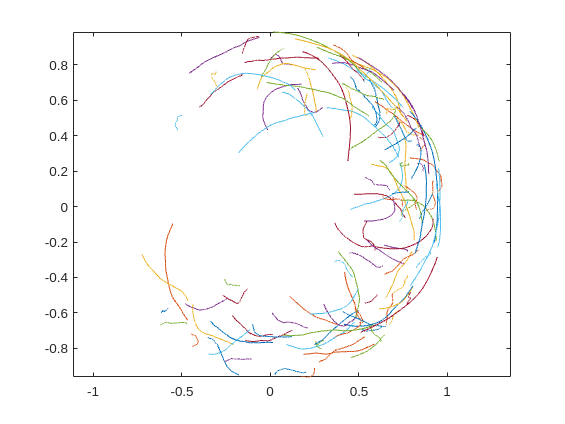

figure()
for i = 1:num_traj
    plot(X_end(i,:,1),X_end(i,:,2))
    hold on
end
axis('equal')

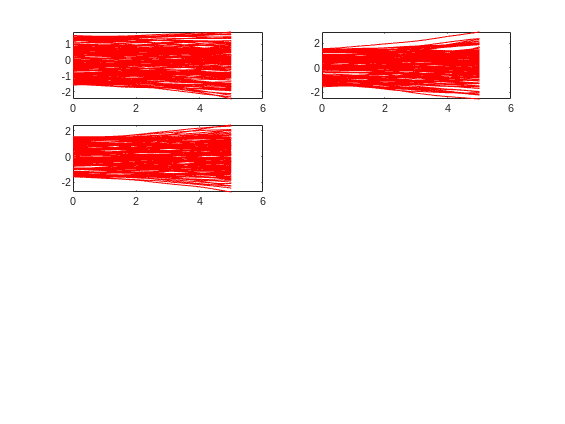

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i), 'r')
        hold on

    end
end

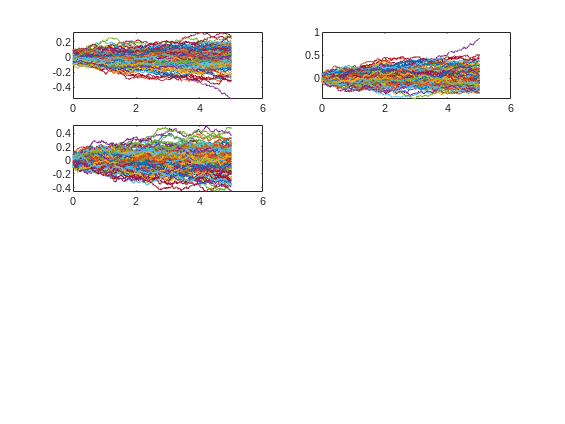

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i+num_states))
        hold on

    end
end

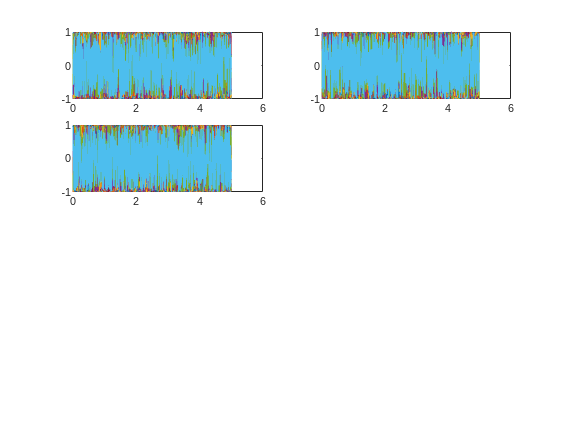

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('tau',num2str(i)))
    for j = 1:num_traj
        plot(t_span(1:end-1),tau(j,:,i))
        hold on

    end
end

% X = X(:,:,[2,4,6,9,11,13]);
% tau = tau(:,:,[2,4,6]);

% save("dynamics\Dataset_MATLAB\X.mat","X")
% save("dynamics\Dataset_MATLAB\X_end.mat","Xend")
% save("dynamics\Dataset_MATLAB\U.mat","tau")



save("dynamics/Dataset_MATLAB/3R/2D/data_rand.mat","X_end","X","tau",'dt','num_snaps',"num_traj")
% save("dynamics\Dataset_MATLAB\X_end.mat","X_end")
% save("dynamics\Dataset_MATLAB\U.mat","tau")



% close all
% skip = 5;
% 
% figure()
% set(gcf, 'Visible', 'on');
% 
% for i = 1:(num_snaps/skip)
%     show(kuka,X(1:num_states,skip*i), 'Frames','off', 'PreservePlot', false);
%     hold on
%     plot3(X_end(1,1:skip*i),X_end(2,1:skip*i),X_end(3,1:skip*i), 'LineWidth',3)
%     drawnow
% end

